SISTEMI DI CONTROLLO

Rappresentazione dei sistemi

num = [1 1];
den = [1 5 6];
H = tf(num,den)

H =
 
      s + 1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties


Ts = 0.01;
H2 = tf(num,den,Ts)

H2 =
 
      z + 1
  -------------
  z^2 + 5 z + 6
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


H3 = tf(num,den,Ts,"variable","z^-1")

H3 =
 
       1 + z^-1
  -------------------
  1 + 5 z^-1 + 6 z^-2
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


sistema con uno zero e due poli

Z = -1;
P = [-2 -3];
K = 3;
Ts = 0.01;
H = zpk(Z,P,K)

H =
 
    3 (s+1)
  -----------
  (s+2) (s+3)
 
Continuous-time zero/pole/gain model.
Model Properties


H2 = zpk(Z,P,K,Ts,"variable","z^-1")

H2 =
 
    3 z^-1 (1+z^-1)
  -------------------
  (1+2z^-1) (1+3z^-1)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


utilizzo lo spazio di stato con ss

A = [0 1;-5 -2];
B = [0;3];
C = [0 1];
D = 0;
H = ss(A,B,C,D)

H =
 
  A = 
       x1  x2
   x1   0   1
   x2  -5  -2
 
  B = 
       u1
   x1   0
   x2   3
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


passare da un modello all'altro usando direttamente la classe

Z = -1;
P = [-2 -3];
K = 3;
Ts = 0.01;
H = zpk(Z,P,K);
H2 = tf(H)

H2 =
 
     3 s + 3
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties


H3 = ss(H)

H3 =
 
  A = 
       x1  x2
   x1  -2   1
   x2   0  -3
 
  B = 
       u1
   x1   0
   x2   2
 
  C = 
         x1    x2
   y1  -1.5   1.5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Mod

per guadagni statici uso uno scalare

H = tf(5)

H =
 
  5
 
Static gain.
Model Properties


Risposte agli ingressi

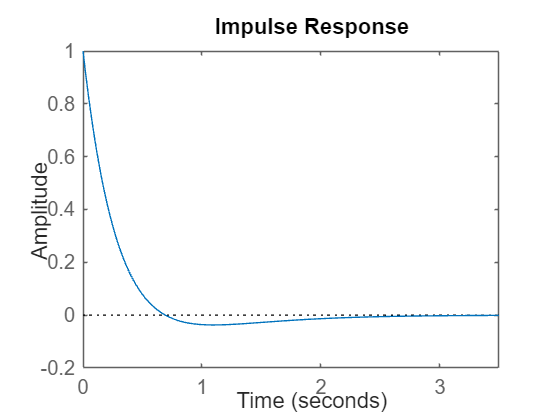

num = [1 1];
den = [1 5 6];
H = tf(num,den);
figure(1);impulse(H)

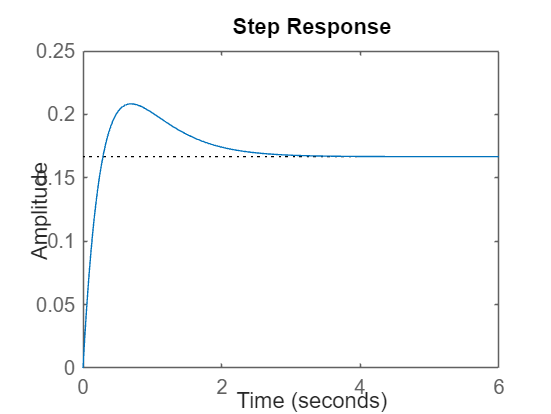

figure(2);step(H)

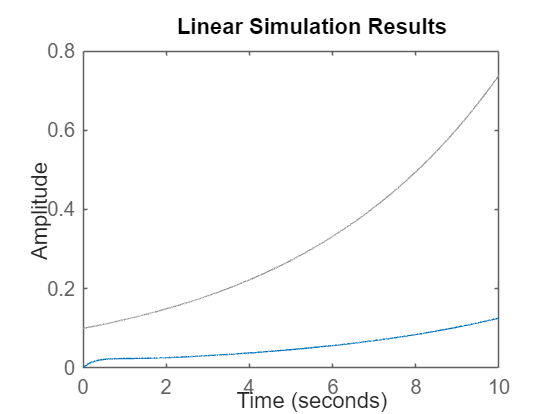

t = 0:0.001:10;
u = 0.1*exp(0.2*t);
figure(3);lsim(H,u,t)

esempio connessione sistemi

num1 = [1 1];
den1 = [1 5 6];
num2 = [1 2];
den2 = [1 4 3];
H1 = tf(num1,den1)

H1 =
 
      s + 1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties


H2 = tf(num2,den2)

H2 =
 
      s + 2
  -------------
  s^2 + 4 s + 3
 
Continuous-time transfer function.
Model Properties


Hs = series(H1,H2)

Hs =
 
           s^2 + 3 s + 2
  --------------------------------
  s^4 + 9 s^3 + 29 s^2 + 39 s + 18
 
Continuous-time transfer function.
Model Properties


Hp = parallel(H1,H2)

Hp =
 
     2 s^3 + 12 s^2 + 23 s + 15
  --------------------------------
  s^4 + 9 s^3 + 29 s^2 + 39 s + 18
 
Continuous-time transfer function.
Model Properties


Hf = feedback(H1,H2)

Hf =
 
       s^3 + 5 s^2 + 7 s + 3
  --------------------------------
  s^4 + 9 s^3 + 30 s^2 + 42 s + 20
 
Continuous-time transfer function.
Model Properties


Diagrammi di Bode

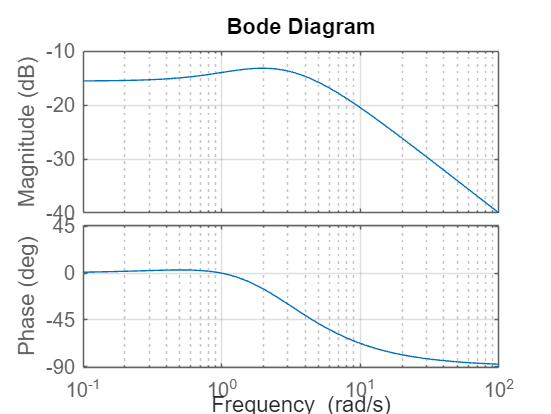

num = [1 1];
den = [1 5 6];
H = tf(num,den);
figure(1);clf;bode(H)
grid on

[Gm,wm] = getPeakGain(H)

Gm = 0.2193

wm = 1.9553

wc = getGainCrossover(H,db2mag(-20))

wc = 9.3664

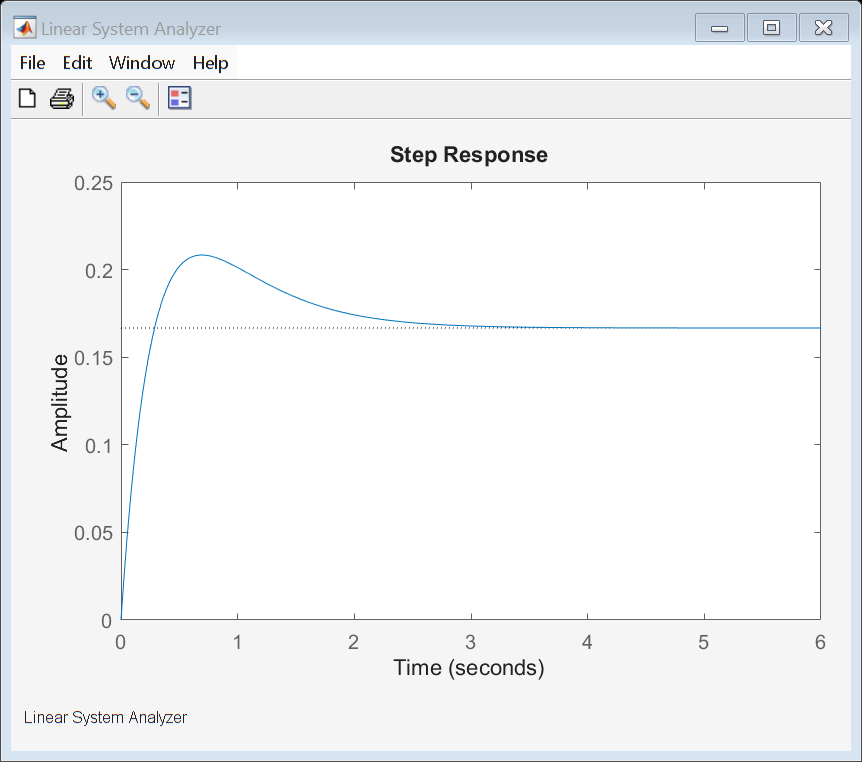

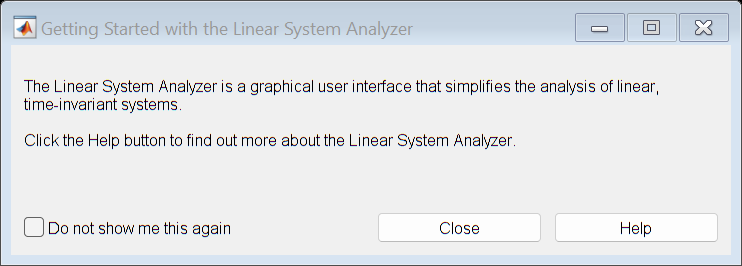

linearSystemAnalyzer(H) %edit plot configuration